# AAE 575 Homework 3 - Problem 2:5 - Joseph Le

## Setup

% LATEX Interpreter for Plots
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
addpath('data_F19')

## Problem 2

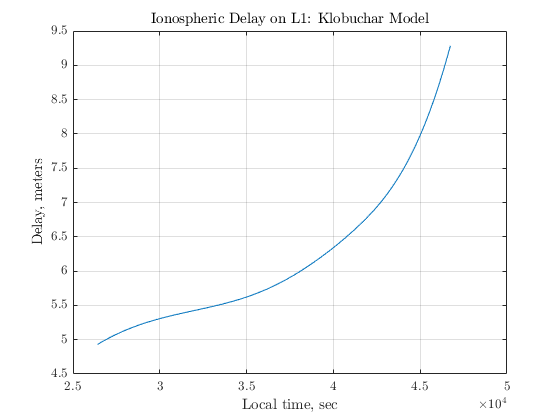

% Loading data
dualfreq = load('dualfreq.sv1');
gpstime = dualfreq(:,1); % sec
sat_az = dualfreq(:,2); sat_el = dualfreq(:,3); % deg
l1prange = dualfreq(:,4); l2prange = dualfreq(:,5); % m
l1cphase = dualfreq(:,6); l2cphase = dualfreq(:,7); % cycles
c = 2.9979E8;

alpha = [0.028, -0.007, -0.119, 0.119]*10^-6;
beta = [137.0, -49.0, -131.0, -262.0]*10^3;
COloc = num2cell([-1288337.0539,-4721990.3382,4078321.6617]); % [m]
COloc_geo = num2cell([39.9914, -105.2601, 1657.7]); % [deg,deg W, m], [lat,long,height]
[COlat, COlong, COheight] = deal(COloc_geo{:});
Re = 6378.1;


% Calculate Psi
psi = 0.0137./(sat_el/180 + 0.11) - 0.022; % sc
% Calculating IPP Coordinates
iono_lat = COlat + psi * 180 .* cosd(sat_az);
iono_long = COlong + psi * 180 .* sind(sat_az) ./ cosd(iono_lat);
if iono_lat > 75
    iono_lat = 75;
elseif iono_lat < -75
    iono_lat = -75;
end
% Defining North Pole Coordinates
pole_lat = 78.3;
pole_long = 291.0;
% Calculating magnetic Latitude 
iono_lat_mag =  iono_lat + 0.064*180*cosd((iono_long/180 - 1.617)*180);
% Calculating Coefficients and Klobuchar Model
A2 = 0; A4 = 0;
for i = 1:4
    A2 = A2 + alpha(i)*(iono_lat_mag/180).^(i-1);
    A4 = A4 + beta(i)*(iono_lat_mag/180).^(i-1);
end
t = 43200*iono_long/180 + gpstime;
x = 2*pi*(t - 50400)./A4;

tauz = 5e-9 + A2 .* (1 - x.^2/2 + x.^4/24);
ind = find(abs(x) >= 1.57);
tauz(ind) = 5e-9;

Fobl_approx = 1.0 + 16.0*(0.53-sat_el/180).^3;
iono_delay_meters = Fobl_approx .* tauz * c;

plot(t,iono_delay_meters)
title('Ionospheric Delay on L1: Klobuchar Model')
xlabel('Local time, sec')
ylabel('Delay, meters')
grid on

## Problem 3:

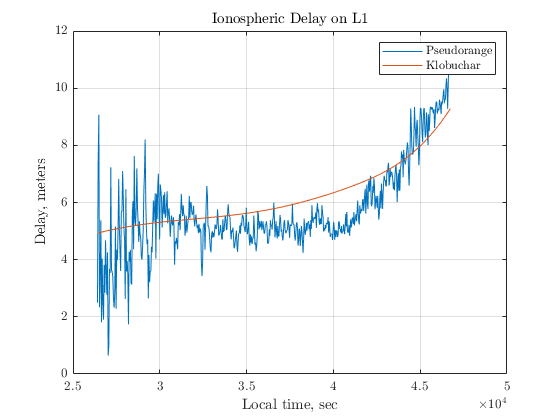

fL1 = 1575.42e6; % hz
fL2 = 1227.6e6; % hz

A = fL1^2*fL2^2/(fL2^2-fL1^2) * (l1prange - l2prange);
l1delay = A/fL1^2;


plot(t,l1delay)
hold on 
plot(t,iono_delay_meters)
title('Ionospheric Delay on L1')
xlabel('Local time, sec')
ylabel('Delay, meters')
legend('Pseudorange','Klobuchar')
grid on
hold off

## Problem 4:

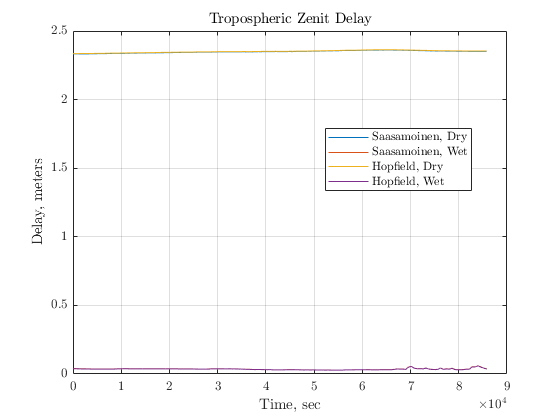

dh = load('DH010600.MET');
year = dh(:,1); month = dh(:,2); day = dh(:,3); hour = dh(:,4); minute = dh(:,5); second = dh(:,6); 
surf_pres = dh(:,7); surf_temp = dh(:,8)+273.15; relhum = dh(:,9)/100;

durmind_lat = 33.390; % deg
durmind_long = -115.79; % deg
durmind_h = -82.94/1000; % km
durmind_h_geoidal = -33.75/1000; % km

% Saastamoinen Model
e0 = 6.108*relhum .* exp((17.15*surf_temp - 4684)./(surf_temp-38.5));
drydelay_S = 0.0022777*(1 + 0.0026*cosd(2*durmind_lat) + 0.00028*durmind_h_geoidal) .* surf_pres;
wetdelay_S = 0.0022777 * (1255./surf_temp + 0.05).*e0;

time = (day - day(1))*24*3600 + hour*3600 + minute*60 + second;

% Hopfield Model
hd = 40136 + 148.72*(surf_temp - 273.16); 
hw = 11000;
drydelay_H = 77.6e-6 * surf_pres./surf_temp .* hd/5;
wetdelay_H = 0.373*e0./(surf_temp.^2) .* hw/5;

% Plotting All
figure
plot(time, drydelay_S)
hold on
plot(time, wetdelay_S)
plot(time, drydelay_H)
plot(time, wetdelay_H)
legend('Saasamoinen, Dry','Saasamoinen, Wet','Hopfield, Dry','Hopfield, Wet','Location',"best")
title('Tropospheric Zenit Delay')
xlabel('Time, sec')
ylabel('Delay, meters')
grid on
hold off

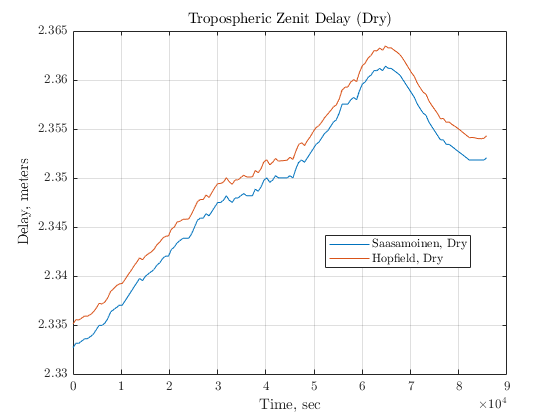

% Plotting Dry
figure
plot(time, drydelay_S)
hold on
plot(time, drydelay_H)
legend('Saasamoinen, Dry','Hopfield, Dry','Location',"best")
title('Tropospheric Zenit Delay (Dry)')
xlabel('Time, sec')
ylabel('Delay, meters')
grid on
hold off

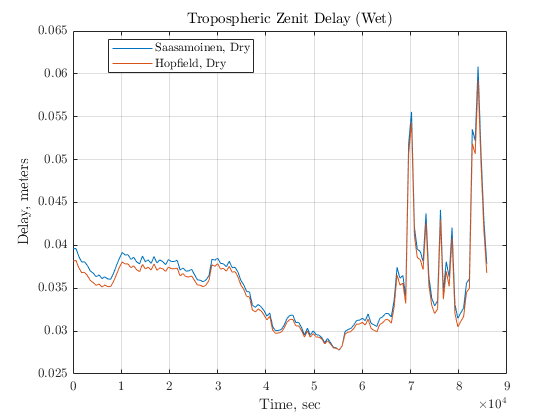

% Plotting Wet
figure
plot(time, wetdelay_S)
hold on
plot(time, wetdelay_H)
legend('Saasamoinen, Dry','Hopfield, Dry','Location',"best")
title('Tropospheric Zenit Delay (Wet)')
xlabel('Time, sec')
ylabel('Delay, meters')
grid on
hold off

## Problem 5:

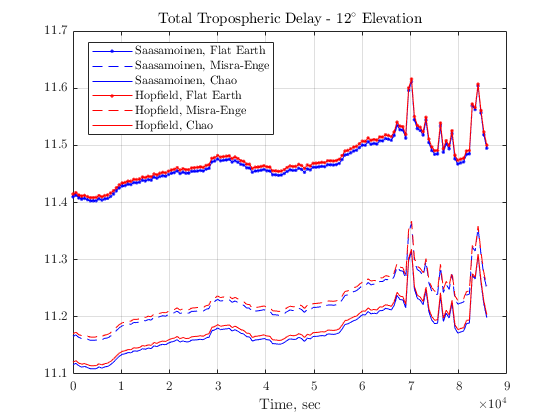

elevation = [12 30 75]; % deg

% Flat Earth Mapping Function
flatmap = 1./sind(elevation);
% Flat Earth Saas
total_delay_S_flat = flatmap .* (drydelay_S + wetdelay_S);
% Flat Earth Hop
total_delay_H_flat = flatmap .* (drydelay_H + wetdelay_H);

% MisraEnge (ME) Mapping Function (5.42)
MEmap = 1./(sqrt(1-(cosd(elevation)/1.001).^2));
% ME Saas
total_delay_S_ME = MEmap .* (drydelay_S + wetdelay_S);
% ME Hop
total_delay_H_ME = MEmap .* (drydelay_H + wetdelay_H);
figure
% plot(time,total_delay)

% Chao Mapping Function
Chaomap_d = 1./(sind(elevation) + 0.00143./(tand(elevation) + 0.0445));
Chaomap_w = 1./(sind(elevation) + 0.00035./(tand(elevation) + 0.0170));
% Chao Saas
total_delay_S_Chao = drydelay_S.*Chaomap_d + wetdelay_S.*Chaomap_w;
% Chao Hop
total_delay_H_Chao = drydelay_H.*Chaomap_d + wetdelay_H.*Chaomap_w;

% Plotting Elevation = 12
figure
plot(time,total_delay_S_flat(:,1),'b.-')
hold on
plot(time,total_delay_S_ME(:,1),'b--')
plot(time,total_delay_S_Chao(:,1),'b')
plot(time,total_delay_H_flat(:,1),'r.-')
plot(time,total_delay_H_ME(:,1),'r--')
plot(time,total_delay_H_Chao(:,1),'r')
title('Total Tropospheric Delay - $12^{\circ}$ Elevation')
xlabel('Time, sec')
legend('Saasamoinen, Flat Earth','Saasamoinen, Misra-Enge','Saasamoinen, Chao','Hopfield, Flat Earth','Hopfield, Misra-Enge','Hopfield, Chao','Location',"best")
grid on
hold off

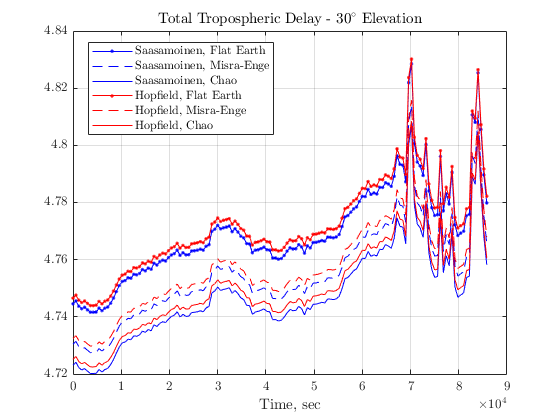

% Plotting Elevation = 30
figure
plot(time,total_delay_S_flat(:,2),'b.-')
hold on
plot(time,total_delay_S_ME(:,2),'b--')
plot(time,total_delay_S_Chao(:,2),'b')
plot(time,total_delay_H_flat(:,2),'r.-')
plot(time,total_delay_H_ME(:,2),'r--')
plot(time,total_delay_H_Chao(:,2),'r')
title('Total Tropospheric Delay - $30^{\circ}$ Elevation')
xlabel('Time, sec')
legend('Saasamoinen, Flat Earth','Saasamoinen, Misra-Enge','Saasamoinen, Chao','Hopfield, Flat Earth','Hopfield, Misra-Enge','Hopfield, Chao','Location',"best")
grid on
hold off

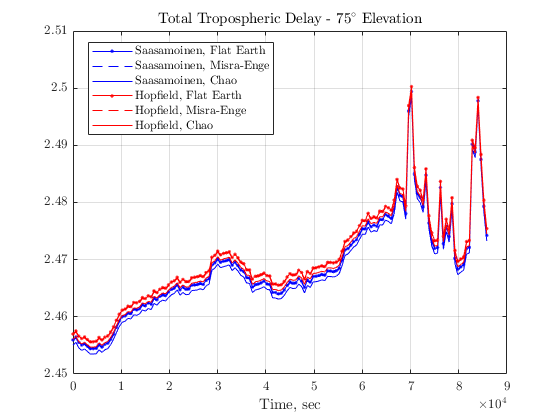


% Plotting Elevation = 30
figure
plot(time,total_delay_S_flat(:,3),'b.-')
hold on
plot(time,total_delay_S_ME(:,3),'b--')
plot(time,total_delay_S_Chao(:,3),'b')
plot(time,total_delay_H_flat(:,3),'r.-')
plot(time,total_delay_H_ME(:,3),'r--')
plot(time,total_delay_H_Chao(:,3),'r')
title('Total Tropospheric Delay - $75^{\circ}$ Elevation')
xlabel('Time, sec')
legend('Saasamoinen, Flat Earth','Saasamoinen, Misra-Enge','Saasamoinen, Chao','Hopfield, Flat Earth','Hopfield, Misra-Enge','Hopfield, Chao','Location',"best")
grid on
hold off

## Functions

#### Function 1: Generate PRN

Function 1: Generating Gold Codes

function G = gpsgen(ICs, taps)
n = length(ICs);
num = 2^n -1;
G = zeros(num,n);
G(1,:) = ICs;
for i = 1:num-1
    temp = mod(sum(G(i,taps)),2); % mod2 add
    G(i+1,2:n) = G(i,1:n-1); % shift
    G(i+1,1) = temp; % replace first index
end
end

Function 2: Binary Phase Shift Keying

function G_b = bpsk(G)
G_b = G;
G_b(G_b == 1) = -1;
G_b(G_b == 0) = 1;
end

Function 3: Cycle Add Generator

function s_i = cycleadd(G1, G2, prntaps)
G2_i = G2(:,1); % create new vector with values of G2
for i = 1:length(G2)
    G2_i(i) = mod(sum(G2(i,prntaps)),2); % phase select values from G2 code with PRN taps
end
s_i = mod(G1+G2_i,2); % modulo-2 add G1 and G2 codes
end

Function 4: Generate PRN Code

function [PRN_code, PRN_code_b] = genprn(prnnumber)
prn_lib = {[2 6], [3 7], [4 8], [5 9], [1 9], [2 10], [1 8], [2 9], [3 10], [2 3],...
    [3 4], [5 6], [6 7], [7 8], [8 9], [9 10], [1 4], [2 5], [3 6], [4 7], [5 8], [6 9],...
    [1 3], [4 6], [5 7], [6 8], [7 9], [8 10], [1 6], [2 7], [3 8], [4 9], [5 10], [4 10],...
    [1 7], [2 8]};
prntaps = cell2mat(prn_lib(prnnumber));
g1taps = [3 10]; % Taps used to generate G1
g2taps = [2 3 6 8 9 10]; % Taps used to generate G2
ICs = [1 1 1 1 1 1 1 1 1 1]; % Initial conditions used to Generate both G1 and G2

% Generating both G1 and G2 using function 1
G1 = gpsgen(ICs, g1taps);
G2 = gpsgen(ICs, g2taps);
% Using function 2 to map G1 and G2: [1,0
% PRN 14
PRN_code = cycleadd(G1(:,10),G2,prntaps); % Using function 3 to generate PRN14
PRN_code_b = bpsk(PRN_code); % Binary shifting PRN14 using function 2
end